## **Average Rate-Energy Region**

clear; clc;
% seed = 100;
% rng(seed)

disp('-------------------------------------------------------');

-------------------------------------------------------


disp('Average Rate-Energy Region');

Average Rate-Energy Region



P_dBm = 30; % Power (dBm)
P = 10^(P_dBm/10);

eta=0.8;

Nt = 8;  % no. of transmit antennas
Nr = 2;  % no. of receive antennas
M = 64;  % no. of IRS shifts

d_x = 40;
beta_TR = 3.6;
beta_TI = 2.2;
beta_IR = 2.2;

psk_level = 2; % PSK order, bit = log2(psk_level);

Ws=[0, 10.^[1:0.1:14]];

Iter = 5;

RateEnergy_Proposed = zeros(2, length(Ws),Iter);
RateEnergy_FullSearch = zeros(2, length(Ws),Iter);
RateEnergy_PH_Mode = zeros(2,Iter);
RateEnergy_TS_rate = zeros(2,Iter);
RateEnergy_TS_energy = zeros(2,Iter);

num_of_active_elements = zeros(length(Ws),Iter);

for iter=1:Iter
    disp('-------------------------------------------------------');
    disp(['Current iteration : ', num2str(iter)]);

    [H, R, T] = IRS_channel(Nt, Nr, M, 0, d_x, beta_TR, beta_TI, beta_IR);

    k=1;
    for w=Ws
        % Proposed algorithm
        [rate_proposed, energy_proposed, ~, alpha, ~] = Proposed_Algorithm(H, R, T, P, eta, w , 0, 0);
        RateEnergy_Proposed(:,k,iter) = [rate_proposed; energy_proposed*10^3];
        num_of_active_elements(k, iter) = sum(abs(alpha))/M;

        if M <= 8
            % Exhaustive algorithm
            [rate_fullsearch, energy_fullsearch, ~, ~, ~] = full_search(H, R, T, P, eta, w ,psk_level);
            RateEnergy_FullSearch(:,k,iter) = [rate_fullsearch; energy_fullsearch*10^3];
        end
        k=k+1;
    end

    % Naive simple algorithms

    % Passive Harvesting mode(=without IRS)
    [Q, rate_PH] =  MIMO_Capacity_with_C(H, zeros(Nt,Nt), P);
    energy_PH = real(eta*trace(T'*Q*T));
    RateEnergy_PH_Mode(:,iter) = [real(rate_PH); energy_PH*10^3];

    % Time sharing mode
    % Reflecting mode(only maximize the transmitted rate(w=0))
    [largest_rate, ~, ~, ~, ~] = Proposed_Algorithm( H, R, T, P, eta, 0, 0, 0);
    RateEnergy_TS_rate(:,iter) = [largest_rate, 0];

    % Harvesting mode(optimize Q for energy harvesting)
    [U, S, V]=svd(T');  Qm=P*V(:,1)*V(:,1)';
    RateEnergy_TS_energy(1,iter)=real(log2(det(eye(size(H,1)) + H*Qm*H')));
    RateEnergy_TS_energy(2,iter)=real(eta*trace(T'*Qm*T)*10^3);
end

-------------------------------------------------------


Current iteration : 1


-------------------------------------------------------


Current iteration : 2


-------------------------------------------------------


Current iteration : 3


-------------------------------------------------------


Current iteration : 4


-------------------------------------------------------


Current iteration : 5


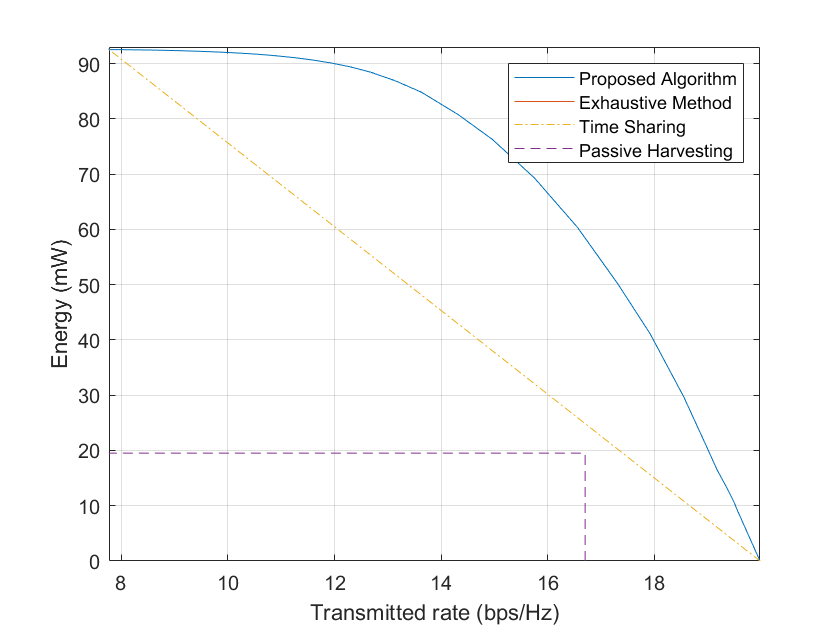

Avg_RateEnergy_Proposed = mean(RateEnergy_Proposed,3);
Avg_RateEnergy_FullSearch = mean(RateEnergy_FullSearch,3);
Avg_RateEnergy_PH_Mode = mean(RateEnergy_PH_Mode,2);
Avg_RateEnergy_TS_rate = mean(RateEnergy_TS_rate,2);
Avg_RateEnergy_TS_energy = mean(RateEnergy_TS_energy,2);

% Rate-energy region
figure
plot(Avg_RateEnergy_Proposed(1,:), Avg_RateEnergy_Proposed(2,:)); hold on;
plot(Avg_RateEnergy_FullSearch(1,:), Avg_RateEnergy_FullSearch(2,:));
plot([Avg_RateEnergy_TS_rate(1) Avg_RateEnergy_TS_energy(1)], [Avg_RateEnergy_TS_rate(2) Avg_RateEnergy_TS_energy(2)], '-.');
plot([Avg_RateEnergy_PH_Mode(1), Avg_RateEnergy_PH_Mode(1), 0], [0, Avg_RateEnergy_PH_Mode(2), Avg_RateEnergy_PH_Mode(2)],'--');
axis([min(Avg_RateEnergy_TS_energy(1)) inf 0 ceil(max(Avg_RateEnergy_TS_energy(2)))]);
xlabel('Transmitted rate (bps/Hz)');
ylabel('Energy (mW)');
legend('Proposed Algorithm','Exhaustive Method','Time Sharing','Passive Harvesting')
grid

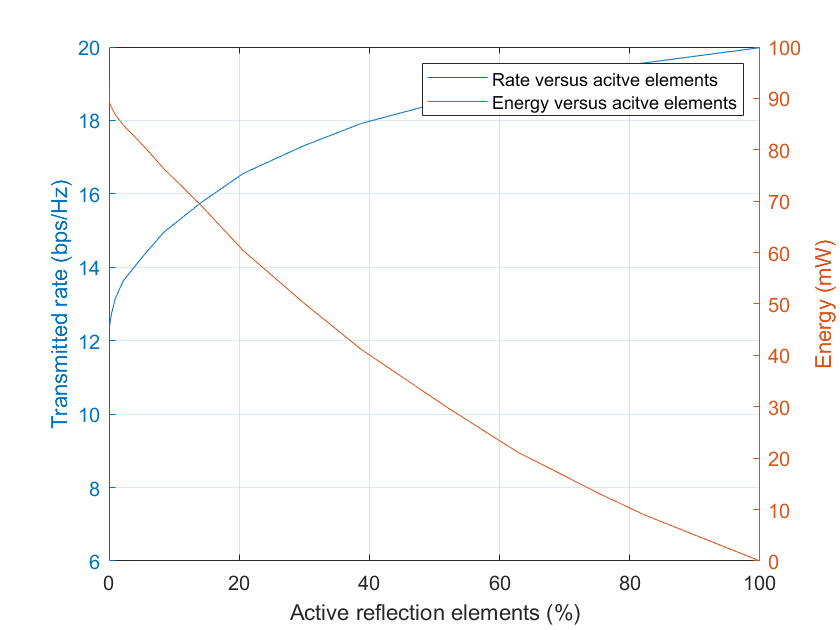


savefig('result\rate_energy_region_Nt('+string(Nt)+')_Nr('+string(Nr)+')_M('+string(M)+')'+'_P('+P_dBm+')'+'_dx('+d_x+')')


Avg_Activity = mean(num_of_active_elements,2);
% Rate and energy with respect to the number of active elements
figure;
yyaxis left
plot(Avg_Activity*100,Avg_RateEnergy_Proposed(1,:),'-'); hold on
ylabel('Transmitted rate (bps/Hz)');

yyaxis right
plot(Avg_Activity(:)*100,Avg_RateEnergy_Proposed(2,:),'-'); hold on
ylabel('Energy (mW)');

xlabel('Active reflection elements (%)');
legend('Rate versus acitve elements','Energy versus acitve elements');
grid


savefig('result\rate(energy)_vs_acive_unit_Nt('+string(Nt)+')_Nr('+string(Nr)+')_M('+string(M)+')'+'_P('+P_dBm+')'+'_dx('+d_x+')')


## **Average Rate-Distance with target energy**

clear; clc;
% seed = 50;
% rng(seed)

disp('-------------------------------------------------------');

-------------------------------------------------------


disp('Average Rate-Distance with target energy');

Average Rate-Distance with target energy



P_dBm = 30; % Power (dBm)
P = 10^(P_dBm/10);

eta=0.8;

Nt = 8;  % no. of transmit antennas
Nr = 2;  % no. of receive antennas
M = 64;  % no. of IRS shifts

d_x_vec = 15:5:40;
beta_TR = 3.6;
beta_TI = 2.2;
beta_IR = 2.2;

psk_level = 0; % PSK order, bit = log2(psk_level), 0:continuous;

target_energy = 90  % mW

target_energy = 90


Iter = 10;

RateEnergy_Proposed = zeros(2, length(d_x_vec),Iter);
RateEnergy_TS_rate = zeros(2,length(d_x_vec),Iter);
RateEnergy_TS_energy = zeros(2,length(d_x_vec),Iter);

for k = 1 : length(d_x_vec)
    d_x = d_x_vec(k);
    disp('-------------------------------------------------------');
    disp(['Current dx : ', num2str(d_x)]);

    iter = 1;
    while(iter<Iter+1)
        
        [H, R, T] = IRS_channel(Nt, Nr, M, 0, d_x, beta_TR, beta_TI, beta_IR);

        w_min = 0;
        w_max = 20;
        for i =1 : 100
            w = (w_min + w_max) / 2;
            w_real = 10^w;

            % Proposed algorithm
            [rate, energy, ~, ~, ~] = Proposed_Algorithm(H, R, T, P, eta, w_real ,psk_level, 0);
            RateEnergy_Proposed(:,k,iter) = [rate; energy*10^3];

            if RateEnergy_Proposed(2,k,iter)>target_energy
                w_max = w;
            else
                w_min = w;
            end

            if abs(RateEnergy_Proposed(2,k,iter)-target_energy) < 10^-3
                break;
            end
        end
        if abs(RateEnergy_Proposed(2,k,iter)-target_energy) > 1
            continue;
        end
        
        % Time sharing mode
        % Reflecting mode(only maximize the transmitted rate(w=0))
        [rate, energy, ~, ~, ~] = Proposed_Algorithm(H, R, T, P, eta, 0, psk_level, 0);
        RateEnergy_TS_rate(:,k,iter) = [rate, 0];

        % Harvesting mode(optimize Q for energy harvesting)
        [U, S, V]=svd(T');  Qm=P*V(:,1)*V(:,1)';
        RateEnergy_TS_energy(1,k,iter)=real(log2(det(eye(size(H,1)) + H*Qm*H')));
        RateEnergy_TS_energy(2,k,iter)=real(eta*trace(T'*Qm*T)*10^3);
        
%         disp('-------------------------------------------------------');
%         disp(['Current iteration : ', num2str(iter)]);
        iter = iter+1;
    end
    check = mean(RateEnergy_Proposed(2,k,:),3);
end

-------------------------------------------------------


Current dx : 15


-------------------------------------------------------


Current dx : 20


-------------------------------------------------------


Current dx : 25


-------------------------------------------------------


Current dx : 30


-------------------------------------------------------


Current dx : 35


-------------------------------------------------------


Current dx : 40


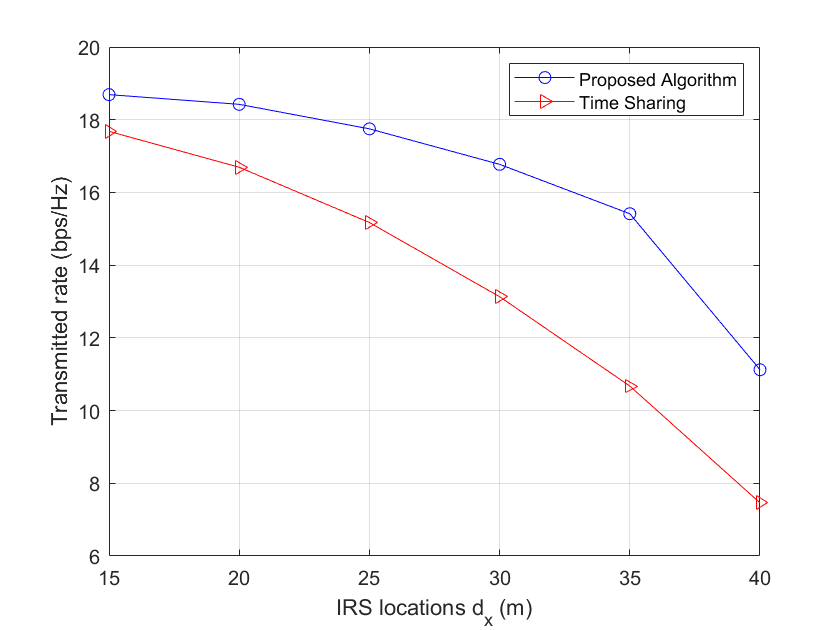

Avg_RateEnergy_Proposed = mean(RateEnergy_Proposed,3);
Avg_RateEnergy_TS_rate = mean(RateEnergy_TS_rate,3);
Avg_RateEnergy_TS_energy = mean(RateEnergy_TS_energy,3);
Rate_TS_target_energy = (Avg_RateEnergy_TS_energy(1,:)-Avg_RateEnergy_TS_rate(1,:))./(Avg_RateEnergy_TS_energy(2,:)-Avg_RateEnergy_TS_rate(2,:))...
    .*(target_energy) + Avg_RateEnergy_TS_rate(1,:);

figure;
plot(d_x_vec, Avg_RateEnergy_Proposed(1,:), '-bo'); hold on;
plot(d_x_vec, Rate_TS_target_energy, '-r>');
ylabel('Transmitted rate (bps/Hz)');
xlabel('IRS locations d_x (m)');
legend('Proposed Algorithm', 'Time Sharing');
grid;


savefig('result\rate_vs_distance_Nt('+string(Nt)+')_Nr('+string(Nr)+')_M('+string(M)+')'+'_P('+P_dBm+')'+'_Energy('+target_energy+'mW)')


## **Average Rate(and Energy) versus Number of M**

clear;
% seed = 50;
% rng(seed)

disp('-------------------------------------------------------------');

-------------------------------------------------------------


disp('Average Rate(and Energy) versus Number of M');

Average Rate(and Energy) versus Number of M




P_dBm = 30; % Power (dBm)
P = 10^(P_dBm/10);

eta=0.8;

Nt = 8;  % no. of transmit antennas
Nr = 2;  % no. of receive antennas
M_vec = [1,20 : 20 : 100];  % no. of IRS shifts

d_x = 40;
beta_TR = 3.6;
beta_TI = 2.2;
beta_IR = 2.2;

psk_level = 0; % PSK order, bit = log2(psk_level);

w = 10^1.;

Iter = 100;

RateEnergy_Proposed  = zeros(2, length(M_vec),Iter);
rate_target_energy = zeros(1,length(M_vec));
Rate_without_IRS = zeros(1,Iter);

for k = 1 : length(M_vec)
    M = M_vec(k);
    disp('-------------------------------------------------------');
    disp(['Current M : ', num2str(M)]);

    for iter=1:Iter
        [H, R, T] = IRS_channel(Nt, Nr, M, 0, d_x, beta_TR, beta_TI, beta_IR);

        [rate, energy, ~, alpha, rate_traj] = Proposed_Algorithm(H, R, T, P, eta, w, psk_level, 0);
        RateEnergy_Proposed(:,k,iter) = [rate; energy*10^3];
    end
end

-------------------------------------------------------


Current M : 1


-------------------------------------------------------


Current M : 20


-------------------------------------------------------


Current M : 40


-------------------------------------------------------


Current M : 60


-------------------------------------------------------


Current M : 80


-------------------------------------------------------


Current M : 100


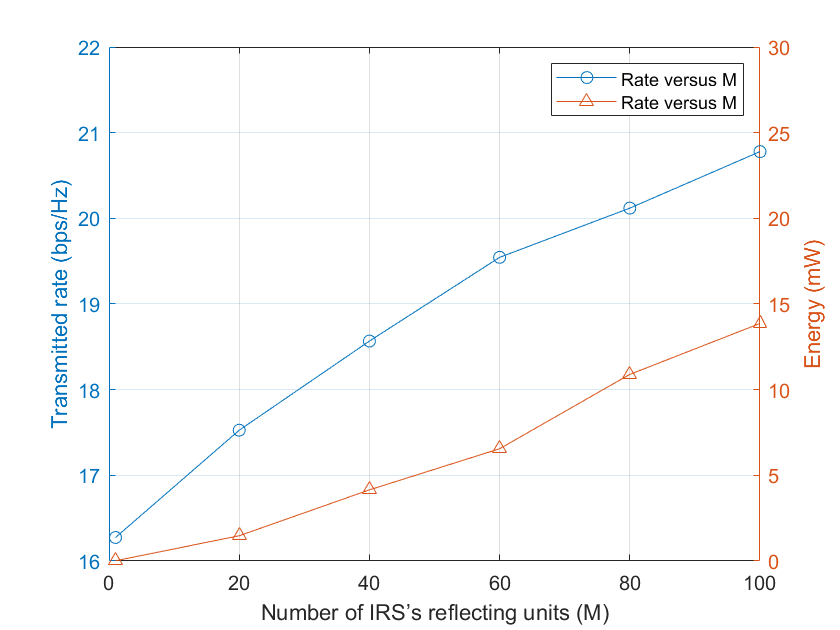

Avg_RateEnergy_Proposed = mean(RateEnergy_Proposed,3);

figure;
yyaxis left
plot(M_vec,Avg_RateEnergy_Proposed(1,:),'-o'); hold on
ylabel('Transmitted rate (bps/Hz)');
axis([0 100 16 22]);

yyaxis right
plot(M_vec, Avg_RateEnergy_Proposed(2,:),'-^'); hold on
ylabel('Energy (mW)');
axis([0 100 0 30]);

xlabel('Number of IRS’s reflecting units (M)');
legend('Rate versus M','Rate versus M');
grid;


savefig('result\rate(energy)_vs_number_of_M_Nt('+string(Nt)+')_Nr('+string(Nr)+')_M('+string(M)+')'+'_P('+P_dBm+')'+'w('+w+')')


## Convergence

clear; clc;
% seed = 100;
% rng(seed)

disp('-------------------------------------------------------');

-------------------------------------------------------


disp('Convergence');

Convergence



P_dBm = 30; % Power (dBm)
P = 10^(P_dBm/10);

eta=0.8; % the power harvesting efficiency of IRS elements

Nt = 8;  % no. of transmit antennas
Nr = 2;  % no. of receive antennas
M  = 4;  % no. of IRS shifts

d_x = 40;
beta_TR = 3.6;
beta_TI = 2.2;
beta_IR = 2.2;

psk_level = 4; % PSK order, bit = log2(psk_level);

w = 10^1.8;

Iter = 10;

RateEnergy_Proposed = zeros(2, Iter);
RateEnergy_FullSearch = zeros(2, Iter);
Obj_Proposed = 0;
Obj_FullSearch = 0;

for iter = 1 : Iter
    disp('-------------------------------------------------------');
    disp(['Current iteration : ', num2str(iter)]);

    [H, R, T] = IRS_channel(Nt, Nr, M, 0, d_x, beta_TR, beta_TI, beta_IR);

    % Proposed algorithm
    [rate_proposed, energy_proposed, ~, alpha_proposed, obj_traj] = Proposed_Algorithm(H, R, T, P, eta, w ,psk_level , 1);
    RateEnergy_Proposed(:, iter) = [rate_proposed; energy_proposed*10^3];
    Obj_Proposed = Obj_Proposed+obj_traj;

    % Exhaustive algorithm
    [rate_fullsearch, energy_fullsearch, ~, alpha_fullsearch, obj_fullsearch] = full_search(H, R, T, P, eta, w ,psk_level);
    RateEnergy_FullSearch(:, iter) = [rate_fullsearch; energy_fullsearch*10^3];
    Obj_FullSearch = Obj_FullSearch+obj_fullsearch;

    % Check the alpha
    [alpha_fullsearch, alpha_proposed, alpha_fullsearch - alpha_proposed];
end

-------------------------------------------------------


Current iteration : 1


-------------------------------------------------------


Current iteration : 2


-------------------------------------------------------


Current iteration : 3


-------------------------------------------------------


Current iteration : 4


-------------------------------------------------------


Current iteration : 5


-------------------------------------------------------


Current iteration : 6


-------------------------------------------------------


Current iteration : 7


-------------------------------------------------------


Current iteration : 8


-------------------------------------------------------


Current iteration : 9


-------------------------------------------------------


Current iteration : 10


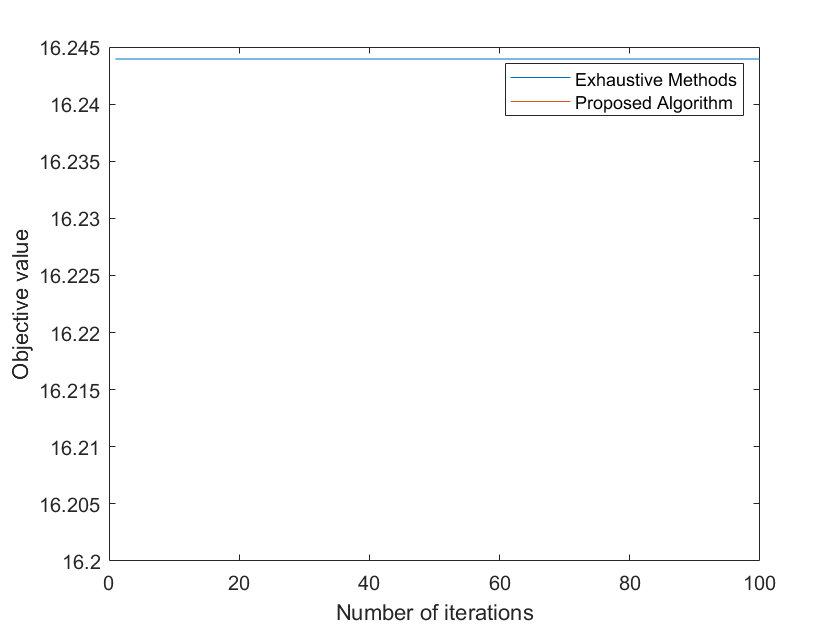

Obj_Proposed = Obj_Proposed/Iter;
Obj_FullSearch = Obj_FullSearch/Iter;


figure
plot(1:length(Obj_Proposed),Obj_FullSearch*ones(1,length(Obj_Proposed)));
hold on;
plot(1:length(Obj_Proposed),Obj_Proposed(:,4))
legend('Exhaustive Methods','Proposed Algorithm')
xlabel('Number of iterations')
ylabel('Objective value')

savefig('result\convergence_Nt('+string(Nt)+')_Nr('+string(Nr)+')_M('+string(M)+')'+'_P('+P_dBm+')'+'_dx('+d_x+')')